# **Tutorial:  Least Squares Regression**

**Numerical Programming: Y.-K. Kim**

Mod. 2024.10

# **Straight Line Curve Fit**

## Problem 

An experiment is conducted that measures the pressure of a gas by heating it in a closed chamber. 

T=[30	40	50	60	70	80];

P=[1.05	1.07	1.09	1.14	1.17	1.21];

### Predict the pressure if the temperature is increased to 150C.

based on Charles's law for ideal gas

P=kT, where k is a constant.

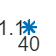

close all, clear all

T=[30	40	50	60	70	80];
P=[1.05	1.07	1.09	1.14	1.17	1.21];
figure(1)
plot(T,P, '*')

xlabel('Temperature (C)')
ylabel('Pressure (atm)')

## Part 1. MATLAB Tutorial

### MATLAB: polyfit()

The best fit curve model is   P=a0+a1(T)

% MATLAB function of curvefitting
% z=[a1, a0]; 
Z=polyfit(T,P,1)

Z =     0.0033    0.9410


Find the yhat

x=30:10:150;

% yopt=Z(1).*x+Z(2);
yopt=polyval(Z,x);  

Plot the best-fit linear function 

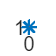

figure(2)
plot(T,P, '*')
hold on
plot(x,yopt)
xlabel('Temperature (C)')
ylabel('Pressure (atm)')

## Exercise 

#### 
$$f(x)=a_0 +a_1x$$


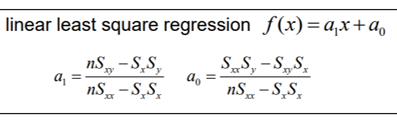


X=T;
Y=P;
%[a0, a1]=linearFit(T,P)

**function [a0,a1] = linearFit_student(X, Y)**

Fill-in the blanks

% function [a0,a1] = linearFit(X, Y)
%
% LinearRegration calculates the coefficients a1 and a0 of the linear
% equation y = a1*x + a0 that best fit n data points.
% Input variables:
% x    A vector with the coordinates x of the data points.
% y    A vector with the coordinates y of the data points.
% Output variable:
% a1   The coefficient a1.
% a0   The coefficient a0.


    %   1. Variable Initialization
    % y = a1*x + a0 
    a1=0; a0=0;
    Sx=0; Sxx=0; Sxy=0;Sy=0;  

    %   2. Check m=length(X) and length(Y)
    m = length(X);
    my = length(Y);
       
    %   3. Is length(X)~= length(Y) ? Exit: Continue 
    if ((m ~= my) || (m==1))
        disp('ERROR: The number of elements in x must be the same as in y.')
        a1=0; a0=0;
        exit
    end
        
    %  4. Solve for Sx, Sxx, Sy, Sxy,  for k=1 to m
    for k=1:m
        Sx=Sx+X(k);        
        % [YOUR CODE GOES HERE]
        % Sxx=_______
        % Sxy=_______
        % Sy=_______
    end

    %  5. Solve for a1, a2    
    % [YOUR CODE GOES HERE]
    % a1=_______
    % a0=_______


    %  Return z=[a0, a1]     

% end   % end of function


Plot the results

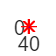

yhat=a0+a1*T;

figure
plot(T,P, '*r')
hold on
plot(T,yhat, '-b')
xlabel('Temperature (C)')
ylabel('Pressure (atm)')

# **Higher-order polynomial  fitting**

## Problem 

Find the optimal higher-order polynomial to fit the given dataset. assume the model has n=3 order polynomial form 

### 
$$f(x)=a_0+a_1x+..+a_{n-1}x^{n-1}+a_nx^n$$


#### 
$$\ {\bf{z}}=[a_0, a_1, ..., a_{n-1}, a_{n} ]^T$$


Xdata = 0:0.4:6;
Ydata = [0, 3, 4.5, 5.8, 5.9, 5.8, 6.2, 7.4, 9.6, 15.6, 20.7, 26.7, 31.1, 35.6, 39.3, 41.5];

## Part 1. MATLAB Tutorial

### MATLAB: polyfit()

The best fit curve model is  $f(x)=a_0+a_1x+..+a_{n-1}x^{n-1}+a_nx^n$

% MATLAB function of curvefitting
% z=[an,..., a1, a0]; 

% polynomial order n=4
n=4;
Z=polyfit(Xdata,Ydata,n)

Z =    -0.0541    1.8030   -1.9882    2.8930


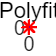


% yhat on the fitted curve:
% yopt=Z(1).*(x.^4)+Z(2).*(x.^3) +...+Z(5);
Yopt=polyval(Z,Xdata);

figure
plot(Xdata,Ydata, '*r')
hold on
plot(Xdata,Yopt, '-b')
xlabel('strain','fontsize',15)
ylabel('stress','fontsize',15)
title('Polyfit')

## Exercise 

The optimal parameters are 

,     

where 

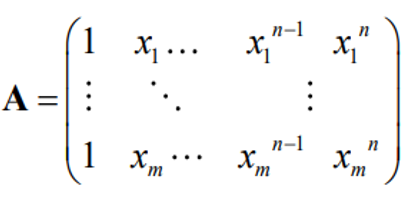

#### 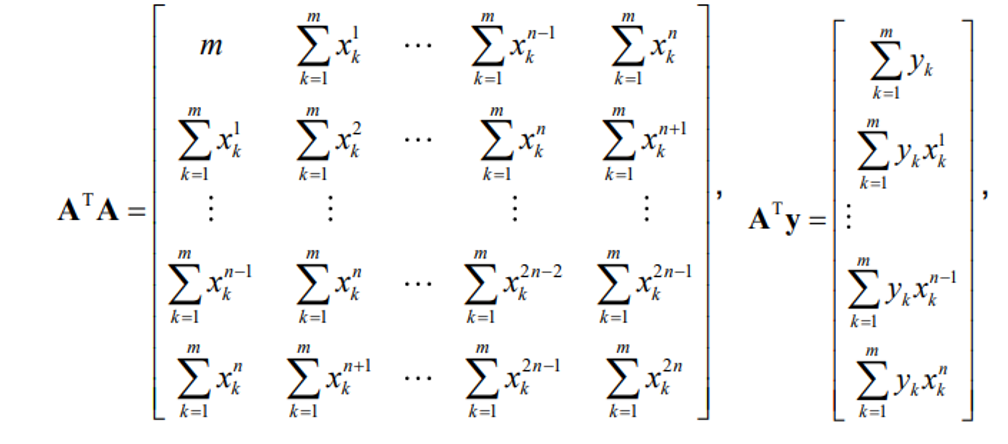



% NP  function output   Z=[a0, a1, ...,an]; 
%
% Zopt=polyFit_student(Xdata,Ydata,n)


% Need to flip  Z order for Matlab function
% Matab inputs in the order of   Z=[an,..., a1, a0]; 
%
% Yopt=polyval(flip(Zopt),Xdata);  

**Function Zopt = polyFit_student(X, Y,n)**

Fill-in the blanks

X=Xdata;
Y=Ydata;

% function Zopt = polyFit_student(X, Y,n)
%
% Input variables:
%   x: A vector with the coordinates x of the data points.
%   y: A vector with the coordinates y of the data points.
% Output variables:
%   Pcoef=[....a4 a3 a2 a1 a0] 


    %   1. Variable Initialization
    %       S:(n+1)x(n+1), where S=A'A
    %       b:(n+1)x1 , where b=(A'y), 
    %       z:(n+1)x1

    Sx=zeros(2*n+1,1); Sxy=zeros(n+1,1); 
    S=zeros(n+1,n+1);  b=zeros(n+1,1); 
    Zopt=zeros(n+1,1);


    %   2. Calculate m=length(X) and my=length(Y)
    m = length(X);
    my = length(Y);
    Zopt=zeros(n+1,1);

    %   3. Is length(X)~= length(Y) ? Exit: Continue     
    if m ~= my
        disp('ERROR: The number of elements in x must be the same as in y.')
        return
    end

    %   4. Is m<(n+1) or n<1 ? Exit: Continue 
    % [YOUR CODE GOES HERE]
              

    %   5. Calculate Sx(i)=sum(xk^(i)), for i=0 to 2n  #(2n+1) and k=1 to m
    for i=0:2*n
        Sx_temp=0;
        for k=1:m
            % [YOUR CODE GOES HERE]
            % Sxtemp=______________            
        end
        Sx(i+1)=Sx_temp;         % Index start from 1 in MATALB
    end
    
    %   6. Construct matrix S with Sx(i).  
    for i = 0:n     % #n+1
        for j=0:n   % #n+1
            % [YOUR CODE GOES HERE]  
            % S(i+1,j+1)=___________________ % Index start from 1 in MATALB            
        end
    end
    % Also, you can make this more efficient for matrix S is symmetric !!


    %   7. Construct vector b=(A'y) 
    %       from Sxy(i)=sum(y*(x^(i))), for i=0 to n  #(n+1)

    for i=0:n       % #n+1
        Sxytemp=0;
        % [YOUR CODE GOES HERE] 
        % [YOUR CODE GOES HERE] 
        % Sxy(i+1,1)=___________        
    end
    b=Sxy;

    
    %   8. Calculate optimal Z=inv(S)*(b)
    % where Z=[a0 a1....an]:  (n+1)x1
    Zopt=(S\b)';    % Zopt=inv(S)*b; 

figure
plot(Xdata,Ydata, '*r')
hold on
plot(Xdata,Yopt, '-b')
xlabel('strain','fontsize',15)
ylabel('stress','fontsize',15)
title('Polyfit')

# **Exponential  Curve Fit**

Exponential Fitting

RC circuit with unknown capacitor C and resistor of 5M$\Omega$

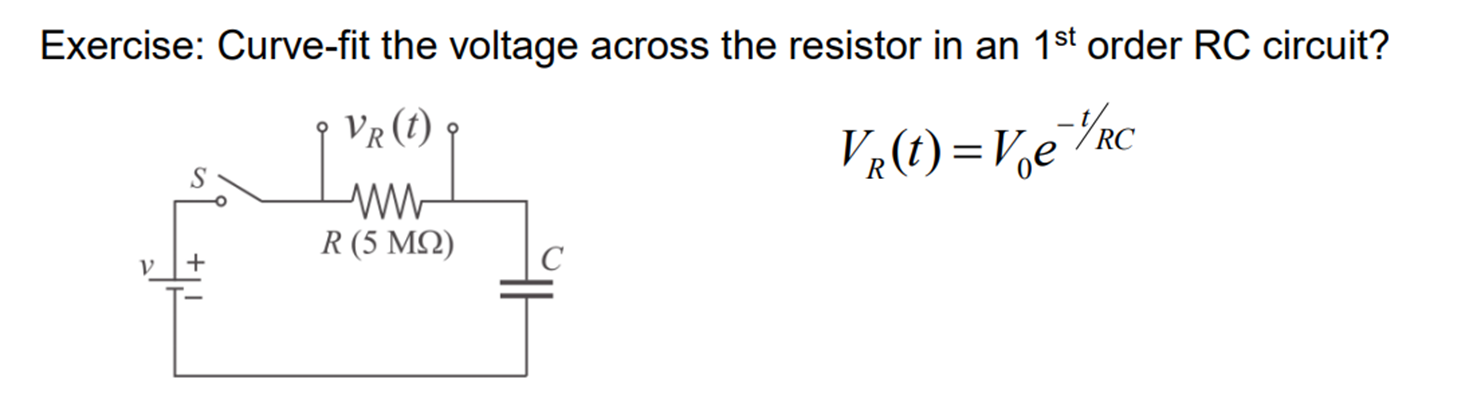

a) Find the capacitance  C from curve fitting

b) Estimate the voltage when time=32sec

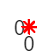

Xdata = 2:2:30;
Ydata = [9.7 8.1 6.6 5.1 4.4 3.7 2.8 2.4 2.0 1.6 1.4 1.1 0.85 0.69 0.6];

figure
plot(Xdata,Ydata, '*r')
xlabel('time (s)','fontsize',15)
ylabel('V_R(volt)','fontsize',15)


%% Exercise
% [YOUR CODE GOES HERE] 
